clear all
close all
clc

**6. Geração Aleatória de Chaves**

1. Considere a funcao Matlab string2hash() que implementa duas funcoes de dispersao diferentes. Utilizando separadamente cada uma destas funcoes de dispersao, simule a insercao das chaves criadas em 6.1 em 3 Chaining Hash Tables, uma de tamanho 5 × 105, outra de tamanho 106 e a terceira de tamanho 2 ×106. Para cada uma das simulacoes: 

(a) Guarde um vetor com os hashcodes obtidos. 

(b) Registe o numero de atribuicoes a cada uma das posicoes de cada Hash Table. 

(c) Calcule o numero de colisoes (em cada Hash Table e para cada funcao de dispersao). 

N = 1e5;
alphabet = ['a':'z','A','Z'];
imin = 6;
imax = 20;
keysA = gerador_chaves(N, imin, imax, alphabet);

arr_N = [5e5 1e6 2e6];
fun = {'djb2', 'sdbm'};
hash_A = cell(length(fun), length(arr_N));
assig_A = cell(length(fun), length(arr_N));
n_col = zeros(length(fun), length(arr_N));
for f=1:length(fun)
    for k=1:length(arr_N)
        hash_A{f,k} = zeros(length(keysA),1);
        assig_A{f,k} = zeros(arr_N(k),1);
        for key=1:length(keysA)
            h = string2hash(keysA{key},fun{f});
            h = mod(h,arr_N(k))+1;
            hash_A{f,k}(key)=h;
            assig_A{f,k}(h)=assig_A{f,k}(h)+1;
        end
        aux = assig_A{f,k}>1;
        n_col(f,k) = sum(assig_A{f,k}(aux)-1);
    end
end

2. Utilizando a informacao obtida no exercicio anterior, compare o desempenho das funcoes de dispersao para cada tamanho diferente da Hash Table, relativamente a: 

(a) Uniformidade, visualizando os histogramas dos hascodes com 100 intervalos; 

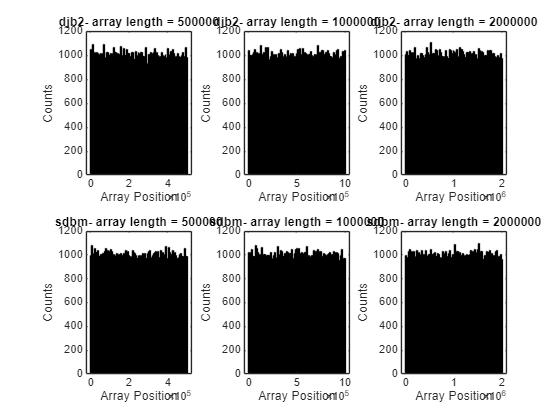

n_bins = 100;
figure(1);
pos = 0;
for f=1:length(fun)
    for k=1:length(arr_N)
        pos=pos+1;
        subplot(length(fun), length(arr_N),pos);
        histogram(hash_A{f,k},n_bins);
        title([fun{f}, '- array length = ',num2str(arr_N(k))]);
        xlabel('Array Position');
        ylabel('Counts');
    end
end

(b) Numero de colisoes e numero maximo de atribuicoes numa mesma posicao da Hash Table.

disp('Number of colitions:');

Number of colitions:


for f = 1:length(fun)
    fprintf('Função hash: %s\n', fun{f});
    for k = 1:length(arr_N)
        fprintf('  Tamanho do array: %.0f -> Número de colisões: %d\n', arr_N(k), n_col(f, k));
    end
    fprintf('\n');
end

Função hash: djb2


  Tamanho do array: 500000 -> Número de colisões: 9304
  Tamanho do array: 1000000 -> Número de colisões: 4762
  Tamanho do array: 2000000 -> Número de colisões: 2386


Função hash: sdbm


  Tamanho do array: 500000 -> Número de colisões: 9464
  Tamanho do array: 1000000 -> Número de colisões: 4884
  Tamanho do array: 2000000 -> Número de colisões: 2450




disp('Maximum Number of colitions:');

Maximum Number of colitions:


for f = 1:length(fun)
    fprintf('Função hash: %s\n', fun{f});
    for k = 1:length(arr_N)
        fprintf('  Tamanho do array: %.0f -> Número máximo de colisões: %d\n', arr_N(k), max(assig_A{f,k}));
    end
    fprintf('\n');
end

Função hash: djb2


  Tamanho do array: 500000 -> Número máximo de colisões: 5
  Tamanho do array: 1000000 -> Número máximo de colisões: 4
  Tamanho do array: 2000000 -> Número máximo de colisões: 3


Função hash: sdbm


  Tamanho do array: 500000 -> Número máximo de colisões: 5
  Tamanho do array: 1000000 -> Número máximo de colisões: 4
  Tamanho do array: 2000000 -> Número máximo de colisões: 3
